clear, close all
% 1. Завантажив з бібліотеки декілька кольорових і чорно-білих зображень різного характеру.
a = imread("lighthouse.png");
b = imread("yellowlily.jpg");
c = imread("cameraman.tif");

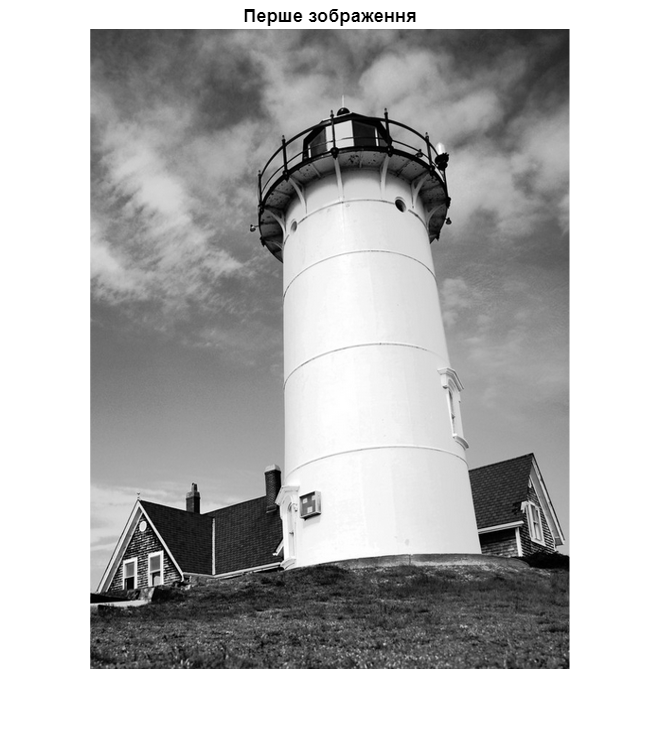

% 2. З використанням функції rgb2gray перетворив кольорові зображення в чорно-білі. Відобразив результат.
agray = rgb2gray(a);
bgray = rgb2gray(b);
figure, imshow(agray), title("Перше зображення")

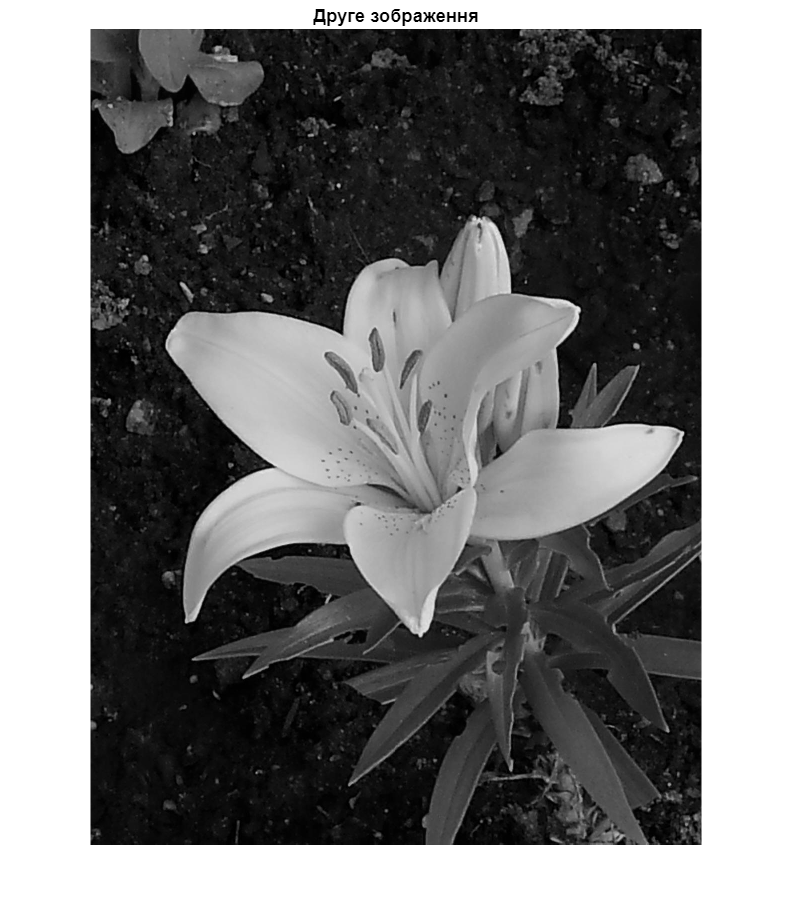

figure, imshow(bgray), title("Друге зображення")

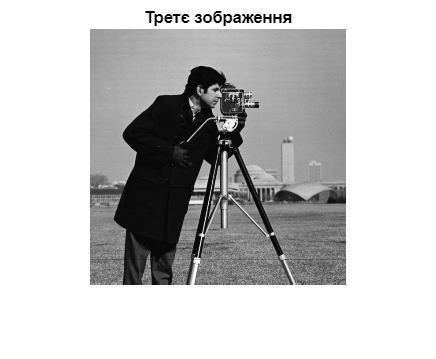

figure, imshow(c), title("Третє зображення")

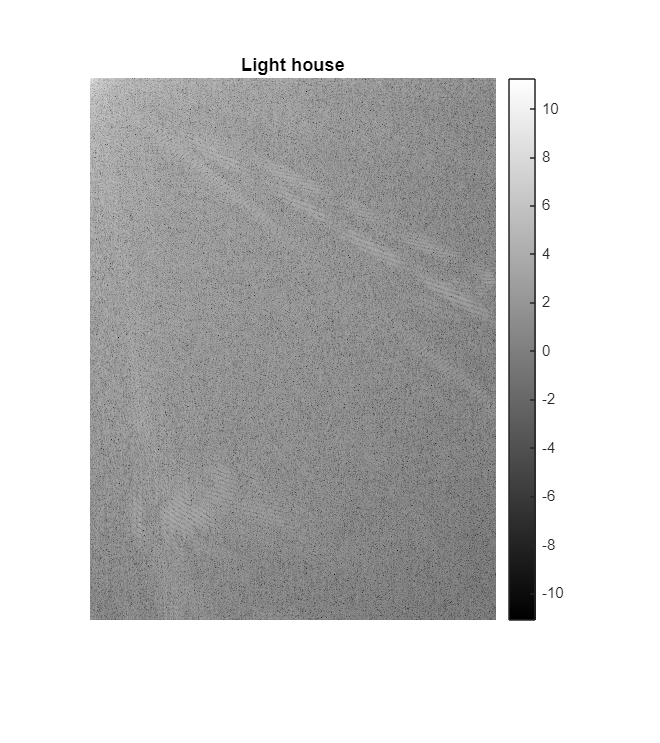

% 3. З використанням функції dct2 виконав дискретне косинусне перетворення зображень. Відобразив результат ДКП у вигляді зображення з використанням функції imshow.
J1 = dct2(agray);
figure; imshow(log(abs(J1)),[]), colorbar, title("Light house");

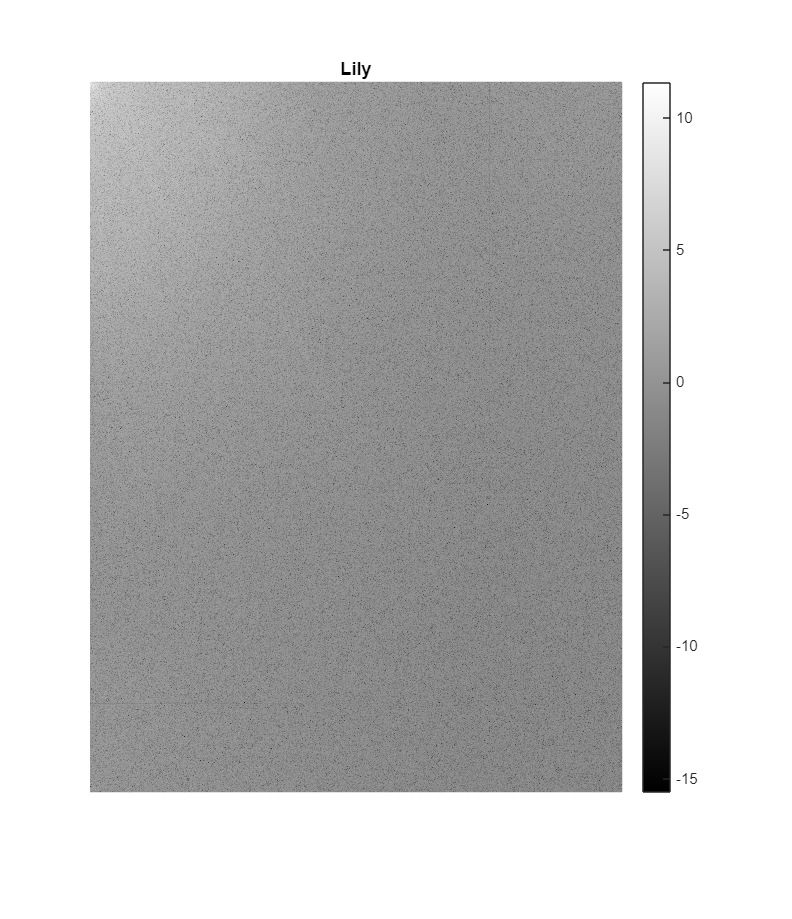

J2 = dct2(bgray);
figure; imshow(log(abs(J2)),[]), colorbar, title("Lily");

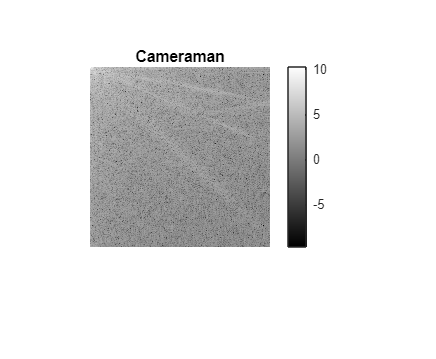

J3 = dct2(c);
figure; imshow(log(abs(J3)),[]), colorbar, title("Cameraman");

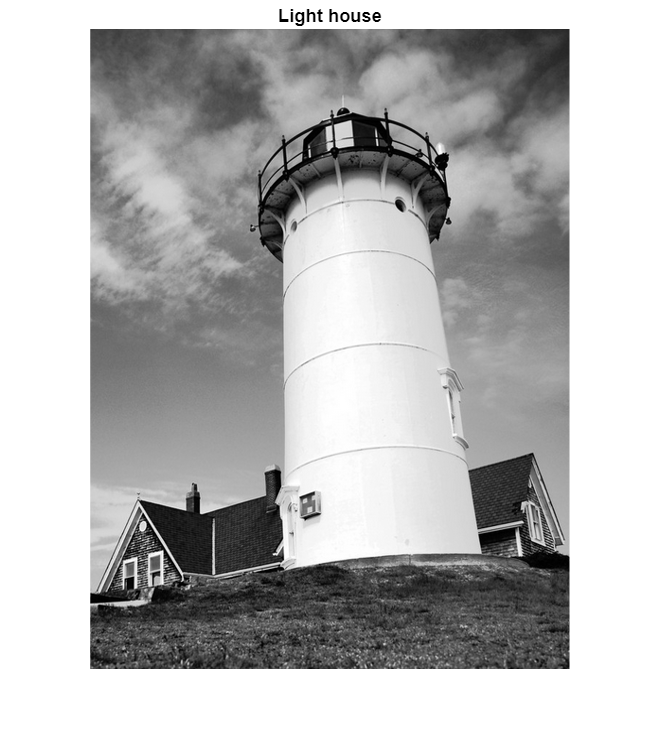

% 4. З використанням функції idct2 відновив зображення за його ДКП-спектру.
K1 = idct2(J1);
figure, imshow(K1,[0 255]), title("Light house");

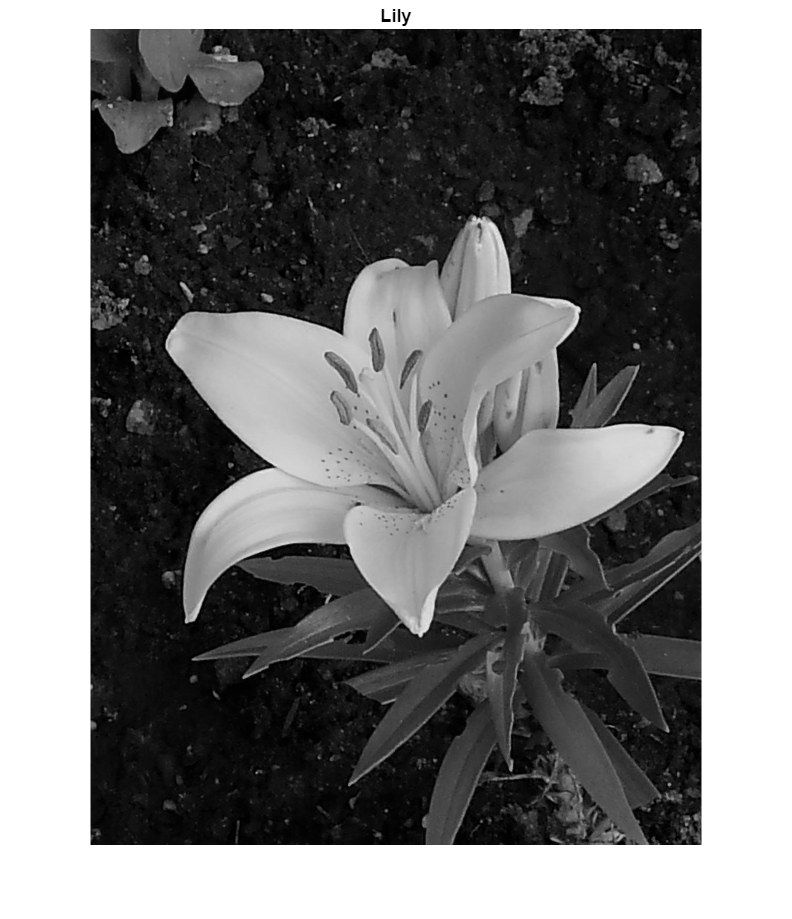

K2 = idct2(J2);
figure, imshow(K2,[0 255]), title("Lily");

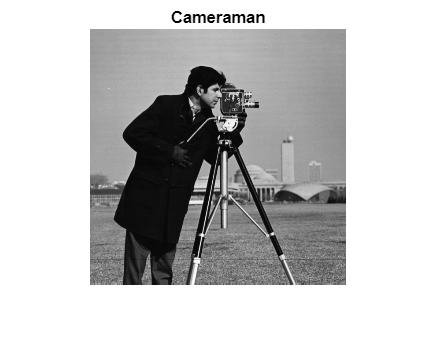

K3 = idct2(J3);
figure, imshow(K3,[0 255]), title("Cameraman");

% 5. З використанням процедури целочислового ділення/множення J = N*round(J*N); виконав квантування результатів ДКП для різних значень кроку квантування N.
N = 10; 
J1_quantized = N * round(J1/N);
J2_quantized = N * round(J2/N);
J3_quantized = N * round(J3/N);
% Пояснення - Процедура J = N * round(J / N) виконує квантування ДКП-коефіцієнтів: кожне значення округлюється до найближчого кратного числа N. 
% Це зменшує точність представлення даних, що призводить до втрати частини дрібної інформації, але дозволяє значно зменшити кількість унікальних значень 
% і підготувати дані до стиснення.

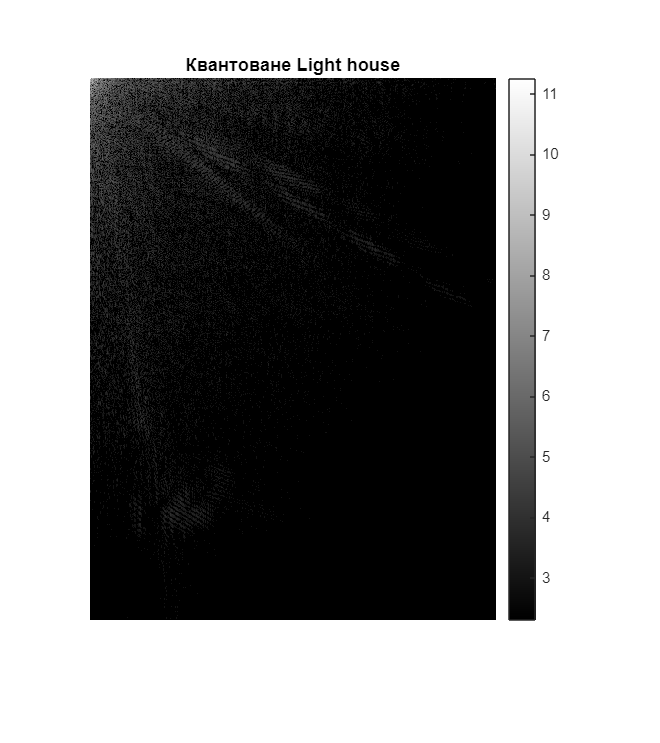

% 6. Відобразив результати у вигляді зображення ( як і раніше для ДКП – у логарифмічному масштабі). Поясніть вигляд отриманих даних.
figure, imshow(log(abs(J1_quantized)), []), colorbar, title("Квантоване Light house");

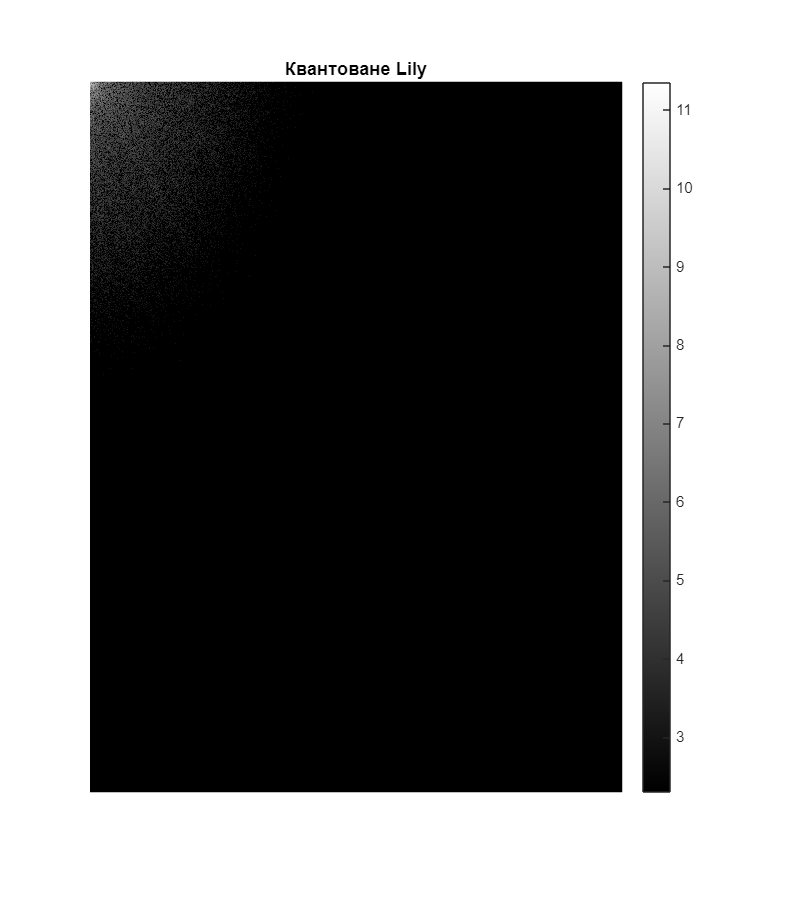

figure, imshow(log(abs(J2_quantized)), []), colorbar, title("Квантоване Lily");

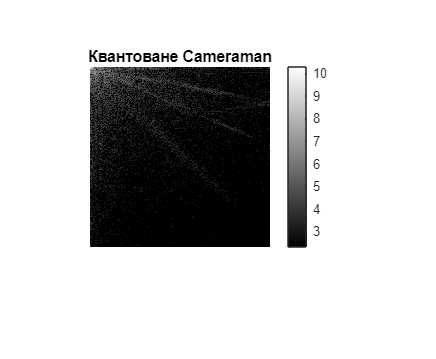

figure, imshow(log(abs(J3_quantized)), []), colorbar, title("Квантоване Cameraman");

% Пояснення - Після квантування ДКП-спектр на вигляд стає грубішим і менш деталізованим. При відображенні в логарифмічному масштабі видно, 
% що багато коефіцієнтів стали нульовими або повторюваними. Зникають тонкі переходи, зменшується кількість яскравих точок, особливо в області високих частот.

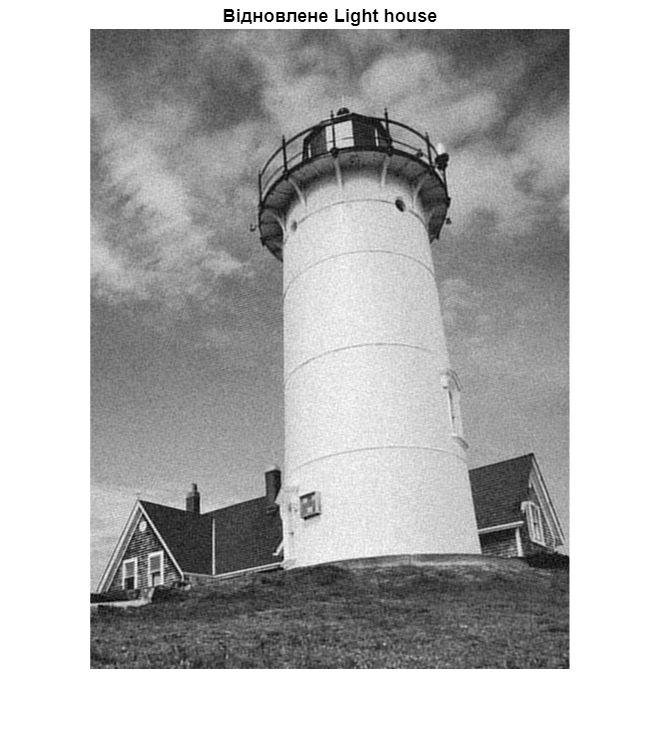

% 7. З використанням функції idct2 відновив зображення за квантованим ДКП-спектром.
K1_quantized = idct2(J1_quantized);
K2_quantized = idct2(J2_quantized);
K3_quantized = idct2(J3_quantized);
figure, imshow(K1_quantized, []), title("Відновлене Light house");

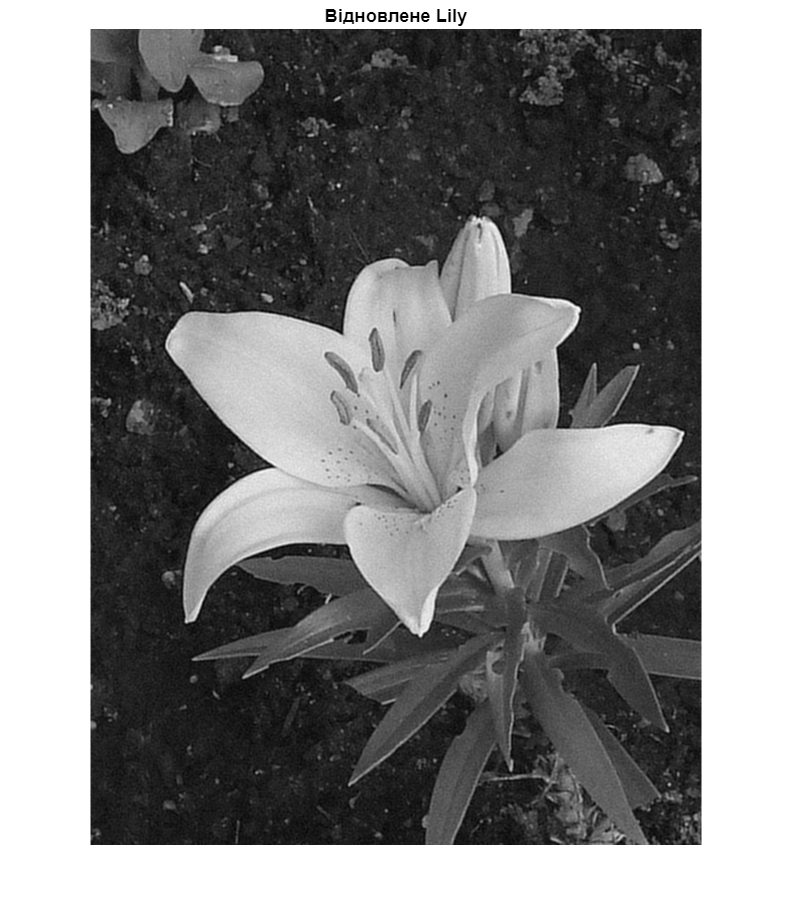

figure, imshow(K2_quantized, []), title("Відновлене Lily");

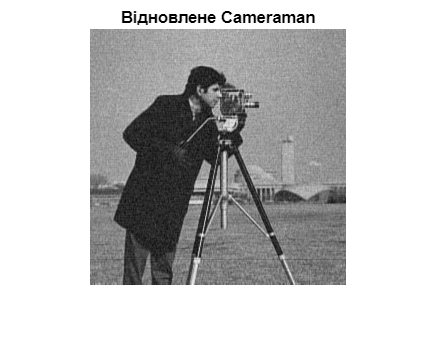

figure, imshow(K3_quantized, []), title("Відновлене Cameraman");

% Пояснення - Відновлені зображення з квантованого ДКП при малому кроці квантування виглядають майже так само, як оригінал, 
% а при великому — помітно втрачають чіткість, деталі зникають, зображення стає розмитим або блоковим. Втрачається плавність переходів і текстур.

% 8. Поясніть, яка мета досягається квантуванням коефіцієнтів ДКП.
% Квантування коефіцієнтів ДКП використовується для зменшення обсягу даних. Воно дозволяє відкинути незначущі частотні компоненти (переважно високочастотні), 
% які мало впливають на візуальне сприйняття, але займають памʼять. Це забезпечує стиснення із допустимими втратами якості.


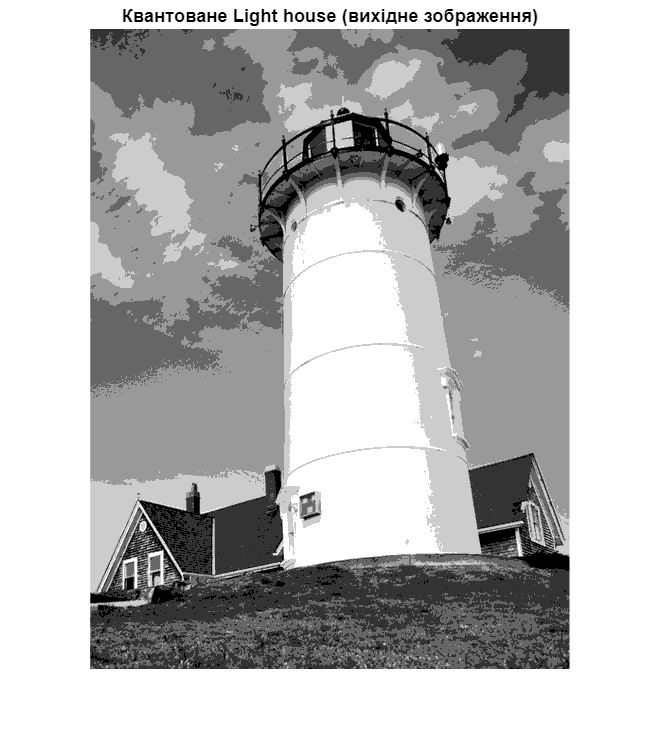

% 9. Чи можливо добитися аналогічної мети й результату, квантуючи вихідне зображення, а не коефіцієнти його ДКП? Перевірив це на практиці, квантуючи 
% з використанням процедури I = (round(J/n))*n вихідні зображення й відобразив отриманий результат.
a_quantized = (round(agray/N)) * N;
b_quantized = (round(bgray/N)) * N;
c_quantized = (round(c/N)) * N;
% Відображення квантованих зображень
figure; imshow(a_quantized, []), title("Квантоване Light house (вихідне зображення)");

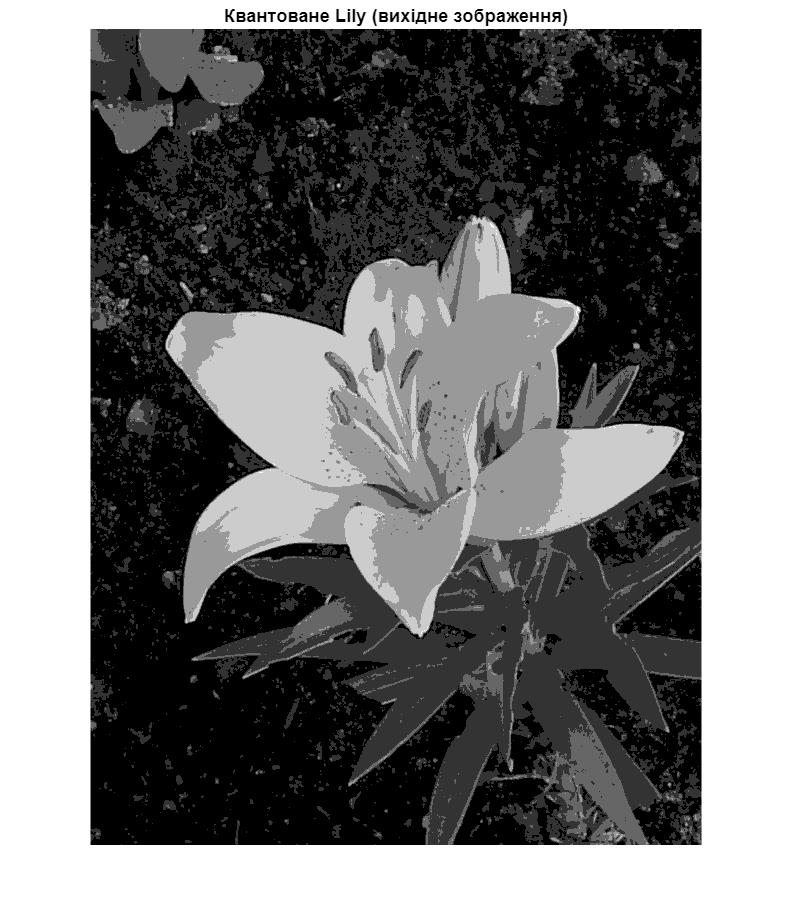

figure; imshow(b_quantized, []), title("Квантоване Lily (вихідне зображення)");

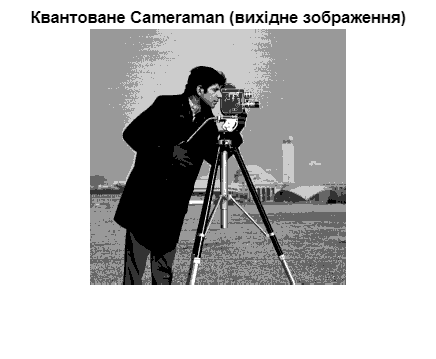

figure; imshow(c_quantized, []), title("Квантоване Cameraman (вихідне зображення)");

% Пояснення - Якщо квантуювати вихідне зображення напряму за тією ж формулою, результат буде гіршим: замість згладженого або компресованого вигляду 
% отримаємо зображення з грубими переходами, ефектом "сходинок" і втратою плавності. Такий підхід не дозволяє вибірково впливати на різні частоти, тому якість падає швидше.

% 10. Які недоліки ви бачите в стисненні зображень із використанням його ДКП і квантування коефіцієнтів ДКП?
% Основні недоліки методу полягають у втраті інформації, особливо при високих рівнях квантування, появі помітних артефактів, таких як блокові структури, 
% а також нерівномірності втрат — одні області зображення можуть залишатися чіткими, інші спотворюються. Метод не завжди ефективний для зображень 
% із великою кількістю дрібних деталей.